
clear all;
close all;

X = [6 6;6 8;7 6;7 7;8 6;8 7;8 9;9 5;9 8;10 4;10 2;11 3;4 5;4 6;5 4;5 5;6 4;7 5;9 7;10 5;10 6;10 7;11 8];
Y = [1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 2; 2; 2; 2; 2; 2; 2; 2; 2; 2; 2];


## Gaussian Bayes

class1 = X(Y==1,:);
class2 = X(Y==2,:);
mean1 = mean(class1);
mean2 = mean(class2);
Cov1 = cov(class1(:,1),class1(:,2));
Cov2 = cov(class2(:,1),class2(:,2));
P1 = size(class1,1)/size(X,1);
P2 = size(class2,1)/size(X,1);


f= disc([0 0],Cov1,mean1,Cov2,mean2,P1,P2);
x1 = disc([1 0],Cov1,mean1,Cov2,mean2,P1,P2)-f;
a = (disc([2 0],Cov1,mean1,Cov2,mean2,P1,P2)-f)/2-x1;
d = x1-a;
x2 = disc([0 1],Cov1,mean1,Cov2,mean2,P1,P2)-f;
c = (disc([0 2],Cov1,mean1,Cov2,mean2,P1,P2)-f)/2-x2;
e = x2 - c;
b = disc([1 1],Cov1,mean1,Cov2,mean2,P1,P2)-f - x1 - x2;

norm(mean1-mean2);
label = zeros(size(Y,1),1);
gaussBayesCorrect = 0;
for i=1:size(Y,1)
    if disc(X(i,:),Cov1,mean1,Cov2,mean2,P1,P2) > 0
        label(i) = 1;
    else
        label(i) = 2;
    end
    if label(i) == Y(i)
        gaussBayesCorrect = gaussBayesCorrect+1;
    end
end
gaussBayesCorrect;

## kNN classifier

kNNLoss = zeros(1, size(X,1));
for i=1:11
    pomocna = zeros(size(X,1),1);
    for j=1:size(X,1)
        pomocna(j) = knnPredict(X(j,:),X,i,Y);
        if pomocna(j) == Y(j)
            kNNLoss(i) = kNNLoss(i) + 1;
        end
    end
    i;
    pomocna;
%     kNNLoss(i) = kfoldLoss(crossval(MdlKnn));
end
kNNLoss

kNNLoss =     17    17    20    18    18    16    18    13    14    12    10     0     0     0     0     0     0     0     0     0     0     0     0


[val, idx] = max(kNNLoss);

labelKnn = zeros(size(X,1),1);
for j=1:size(X,1)
    labelKnn(j) = knnPredict(X(j,:),X,idx,Y);
end
knnCorrect = 0;
for i=1:size(Y,1)
%     labelKnn(i,1)
    if labelKnn(i,1) == Y(i,1)
        knnCorrect = knnCorrect+1;
    end
end
knnCorrect

knnCorrect = 20

## Mahalanobis classifier

fm = mahaldisc([0 0],Cov1,mean1,Cov2,mean2);
y1 = mahaldisc([1 0],Cov1,mean1,Cov2,mean2) -fm;
am = (mahaldisc([2 0],Cov1,mean1,Cov2,mean2)-fm)/2-y1;
dm = y1 - am;
y2 = mahaldisc([0 1],Cov1,mean1,Cov2,mean2) -fm;
cm = (mahaldisc([0 2],Cov1,mean1,Cov2,mean2) -fm)/2-y2;
em = y2 - cm;
bm = mahaldisc([1 1],Cov1,mean1,Cov2,mean2)-fm - y1 - y2;

labelMahal = zeros(size(X,1),1);
mahalCorrect = 0;
for i=1:size(X,1)
    if mahaldisc(X(i,:),Cov1,mean1,Cov2,mean2) < 0
        labelMahal(i) = 1;
    else
        labelMahal(i) = 2;
    end
    if labelMahal(i) == Y(i)
        mahalCorrect = mahalCorrect + 1;
    end
end

## Exercise 3 part 3

testSet = [8 3;8 5; 8 8;10 8];

label3Gauss = zeros(4,1);
label3Mahal = zeros(4,1);
for i=1:4
    if mahaldisc(testSet(i,:),Cov1,mean1,Cov2,mean2) < 0
        label3Mahal(i) = 1;
    else
        label3Mahal(i) = 2;
    end
    if disc(testSet(i,:),Cov1,mean1,Cov2,mean2,P1,P2) > 0
        label3Gauss(i) = 1;
    else
        label3Gauss(i) = 2;
    end
end

label3Knn = zeros(size(testSet,1),1);
for i=1:size(testSet,1)
    label3Knn(i) = knnPredict(testSet(i,:),X,idx,labelKnn);
end
label3Knn

label3Knn =      1
     1
     1
     2


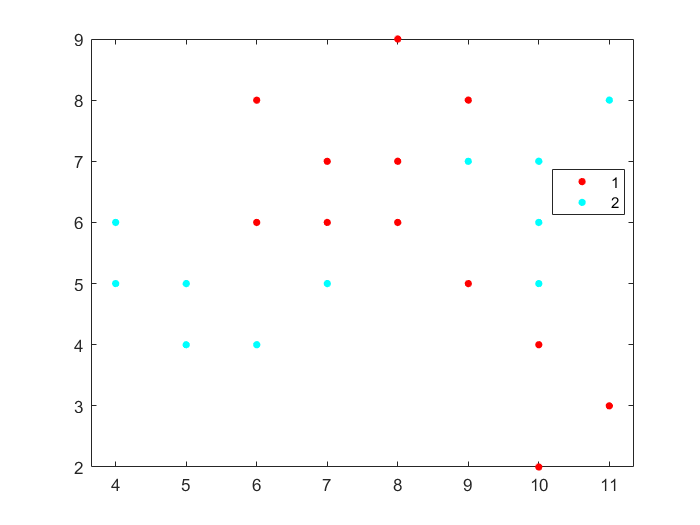

figure
gscatter(X(:,1),X(:,2),Y);
hold off

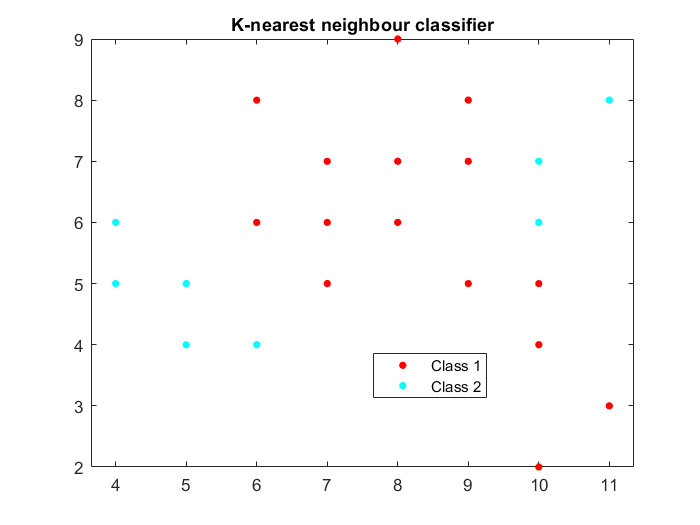

figure;
gscatter(X(:,1),X(:,2),labelKnn);
legend('Class 1', 'Class 2')
title('K-nearest neighbour classifier')

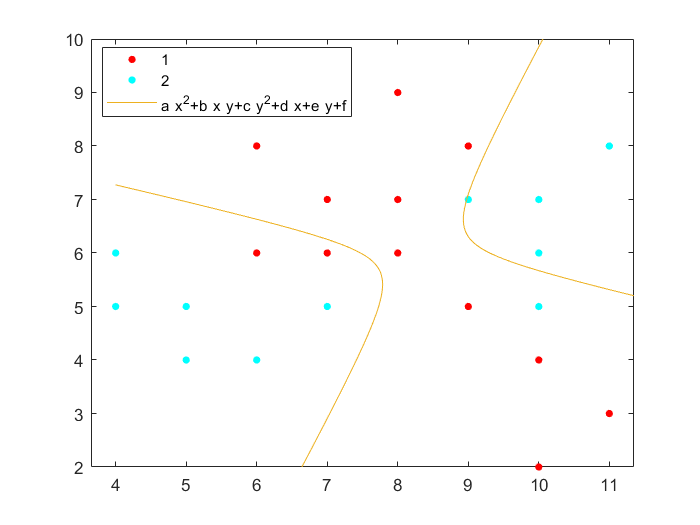

figure;
gscatter(X(:,1),X(:,2),Y);
hold on
fimplicit(@(x,y) a*x.^2 + b.*x.*y+c.*y.^2+d.*x+e.*y+f, [4 12 2 10])
hold off

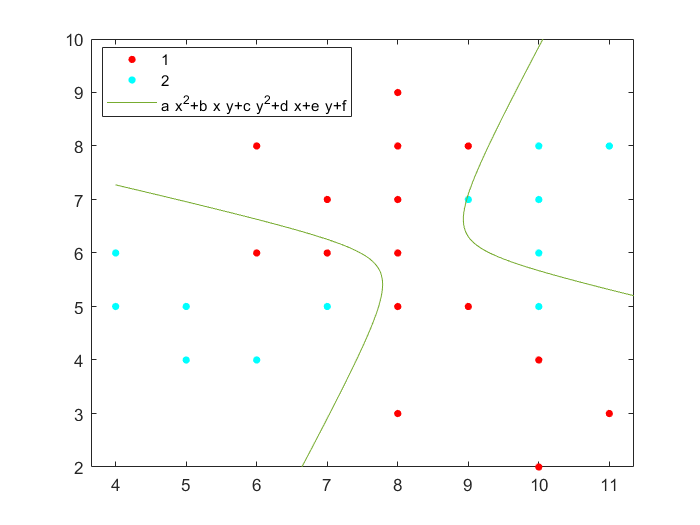

figure;
gscatter(X(:,1),X(:,2),Y);
hold on
gscatter(testSet(:,1),testSet(:,2),label3Gauss);
fimplicit(@(x,y) a*x.^2 + b.*x.*y+c.*y.^2+d.*x+e.*y+f, [4 12 2 10])
hold off

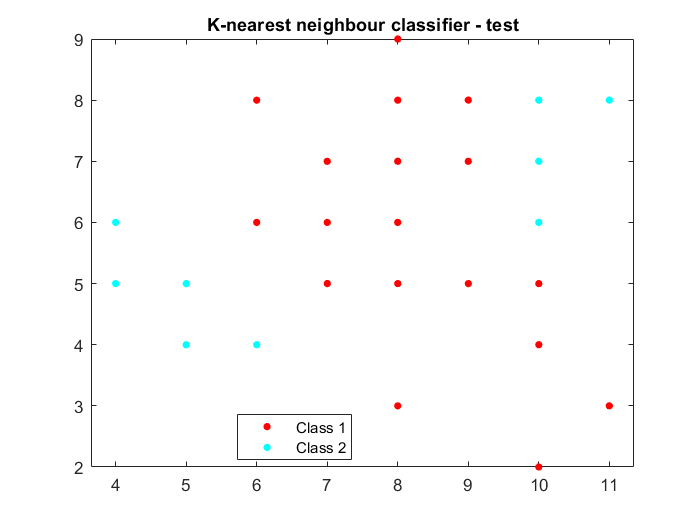

figure;
gscatter(X(:,1),X(:,2),labelKnn);
hold on
gscatter(testSet(:,1),testSet(:,2),label3Knn);
hold off
legend('Class 1', 'Class 2')
title('K-nearest neighbour classifier - test')

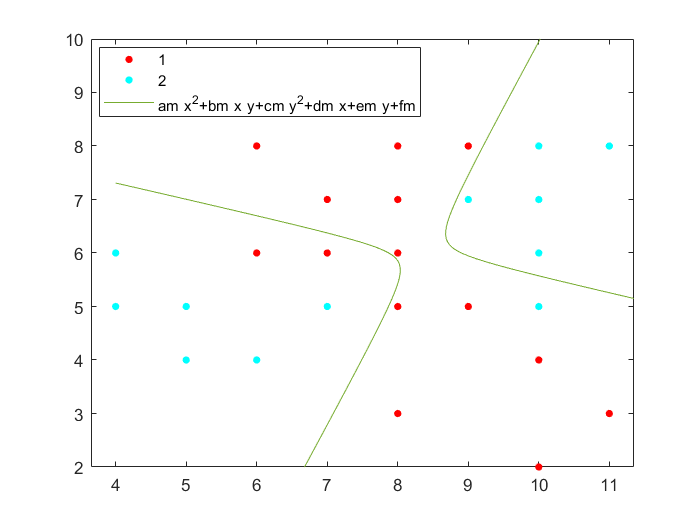


figure;
gscatter(X(:,1),X(:,2),Y);
hold on
gscatter(testSet(:,1),testSet(:,2),label3Mahal);
fimplicit(@(x,y) am*x.^2 + bm.*x.*y+cm.*y.^2+dm.*x+em.*y+fm, [4 12 2 10])
hold off

function d1 = disc1(X,Cov1,mean1,P1)
    d1 = -((X-mean1)*inv(Cov1)*(X-mean1)')/2 - log(det(Cov1))/2 + log(P1);
end

function d = disc(X,Cov1,mean1,Cov2,mean2,P1,P2)
    d = disc1(X,Cov1,mean1,P1)-disc1(X,Cov2,mean2,P2);
end

function d = mahaldisc1(X,Cov1,mean1)
    d = (X-mean1)*inv(Cov1)*(X-mean1)';
end

function d = mahaldisc(X,Cov1,mean1,Cov2,mean2)
    d = mahaldisc1(X,Cov1,mean1)-mahaldisc1(X,Cov2,mean2);
end

function d = eudist(x,y)
    d = sqrt((x(1,1)-y(1,1))^2+(x(1,2)-y(1,2))^2);
end

function label = knnPredict(x,X,K,Y)
    distan = zeros(size(X,1),1);
    for i=1:size(X,1)
        if X(i,:) == x
            distan(i,1) = 100;
        else
            distan(i,1) = eudist(x,X(i,:));
        end
    end
    [xs,index] = sort(distan);
    ones = 0;
    twos = 0;
    for j=1:K
        if Y(index(j)) == 1
            ones = ones + 1;
        else
            twos = twos + 1;
        end
    end
    if ones > twos
        label = 1;
    else
        label = 2;
    end
    
end